# Transient Balance Equations

In engineering, there are 4 common balance equations from conservation principles including mass, momentum, energy, and species. General forms of each equation are shown below with the accumulation term on the left and inlet (in), outlet (out), generation (gen), and consumption (cons) terms on the right side of the equation.


$$\text{Accumulation} = \text{In} - \text{Out} + \text{Generation} - \text{Consumption}$$


[Link to video]

## Mass Balance


$$\frac{dm}{dt}=\frac{d(\rho V)}{dt} = \sum\dot{m}_{in} - \sum\dot{m}_{out}$$


## Species Balance

A species balance tracks the number of moles ($n$) of a species ($A$) in a control volume. The accumulation of $A$, $\frac{d(n_A)}{dt}$, in a control volume is calculated by inlet, outlet, reaction generation, and rection consumption rates.


$$\frac{dn_A}{dt}=\sum\dot{n}_{A_{in}}-\sum\dot{n}_{A_{out}}+\sum\dot{n}_{A_{gen}}-\sum\dot{n}_{A_{cons}}$$


The molar ammount ($n_A$) is often measured as a concentration ($C_A$) and reaction rates are often expressed in terms of a specific reaction rate ($r_A$) as a molar rate of generation per volume.


$$\frac{dc_AV}{dt}=\sum c_{A_{in}}\dot{V}_{in}-\sum c_{A_{out}}\dot{V}_{out} + r_AV$$


## Momentum Balance

A momentum balance is the accumulation of momentum for a control volume equal to the sum of forces ($F$) acting on that control volume.


$$\frac{d(mv)}{dt}=\sum F$$


with $m$ as the mass in the control volume and $v$ as the velocity of the control volume.

## Energy Balance


$$\frac{dE}{dt}=\frac{d(U+K+P)}{dt}=\sum\dot{m}_{in}(\hat{h}_{in} + \frac{v^2_{in}}{2g_c}+\frac{z_{in}g_{in}}{g_c})-\sum\dot{m}_{out}(\hat{h}_{out} + \frac{v^2_{out}}{2g_c}+\frac{z_{out}g_{out}}{g_c})+Q+W_s$$


Kinetic ($K$) and potential ($P$) energy terms are omitted because the internal energy (due to temperature) is typically a much larger contribution than any elevation ($z$) or velocity ($v$) changes of a fluid for most chemical processes.


$$\frac{dh}{dt}=\sum\dot{m}_{in}\hat{h}_{in} - \sum\dot{m}_{out}\hat{h}_{out} +Q +W_s$$


The enthalpy, $h$, is related to the temperature as $m\cdot c_p(T-T_{ref})$ where $c_p$ is the heat cpacity. With a constant reference temperature ($T_{ref}$), this refuces to the following:


$$m\ c_p\frac{dT}{dt} = \sum\dot{m}_{in}c_p(T_{in}-T_{ref}) - \sum\dot{m}_{out}c_p(T_{out}-T_{ref}) + Q + W_s$$


## Exercise:

Use a mass, species, and energy balance to describe the dynamic response in volume, concentration, and temperature of a well-mixed vessel.

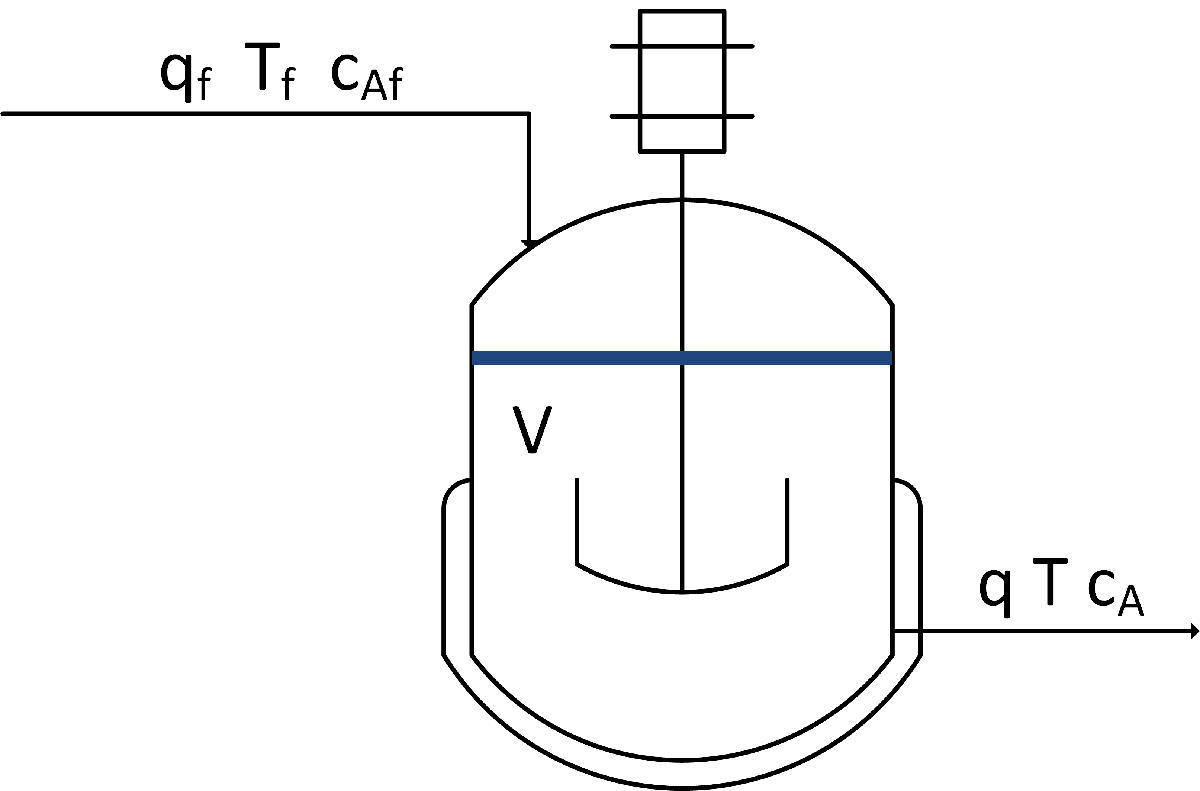

The inlet ($q_f$) and outlet ($q$) volumetric flowrates, feed concentration ($Ca_f$), and inlet temperature ($T_f$) can be adjusted. Initial conditions for the vessel are $V=1.0 \ \text{L}$, $Ca = 0.0 \ \frac{\text{mol}}{\text{L}}$ mol/L, and $T = 350.0 \ \text{K}$. There is no reaction and no significant heat added by the mixer. There is a cooling jacket that can be used to adjust the outlet temperature. Show step changes in the process inputs.

### Solution:

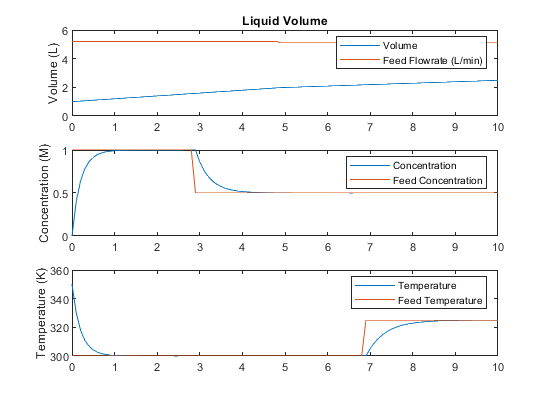

height = 400

% Clear all previous data
clc; clear all; close all;

% Initial Conditions
V0 = 1.0;  % L
Ca0 = 0.0;  % Initial Concentration
T0 = 350.0;  % deg K

% SIMULATE STEP CHANGES BELOW
%%%%%%%%%%%%%%%%%%%%
% time interval (min)
time = linspace(0, 10, 101);

% Inlet flowrate (L/min)
qf = ones(length(time), 1) * 5.2;
qf(50:end) = 5.1;

% Outlet Flowrate (L/min)
q = ones(length(time), 1) * 5.0;

% Feed concentration (mol/L)
Caf = ones(length(time), 1) * 1.0;
Caf(30:end) = 0.5;

% Feed Temperature (K)
Tf = ones(length(time), 1) * 300.0;
Tf(70:end) = 325.0;

% Results storage
V = ones(length(time), 1) * V0;
Ca = ones(length(time), 1) * Ca0;
T = ones(length(time), 1) * T0;

% Loop through time steps
y0 = [V0; Ca0; T0];
for i = 1:(length(time)-1)
    ts = [time(1) time(2)];
    [t, y] = ode45(@(t, y) Tank(t, y, q(i), qf(i), Caf(i), Tf(i)), ts, y0);
    % assign output to storage arrays
    y0 = y(end,:);
    V(i+1) = y0(1);
    Ca(i+1) = y0(2);
    T(i+1) = y0(3);
end
%%%%%%%%%%%%%%%%%%%%

% PLOT RESULTS BELOW
%%%%%%%%%%%%%%%%%%%%
subplot(3,1,1)
plot(time, [V, qf])
title('Liquid Volume')
ylabel('Volume (L)')
legend({'Volume', 'Feed Flowrate (L/min)'})
subplot(3,1,2)
plot(time,[Ca, Caf])
ylabel('Concentration (M)')
legend({'Concentration', 'Feed Concentration'})
subplot(3,1,3)
plot(time,[T, Tf])
ylabel('Temperature (K)')
xlabel('Time (min)')
legend({'Temperature', 'Feed Temperature'})

%%%%%%%%%%%%%%%%%%%%

% DEFINE MODEL OF TANK BELOW
%%%%%%%%%%%%%%%%%%%%

function [output] = Tank(t, y, q, qf, Caf, Tf)
% Parameters
% t (array): Time array
% y (array): [Volume; Concentration A; Temperature] Terms to be integrated
% q (float): Outlet volumetric flow rate (L/min)
% qf (float): Feed volumetric flow rate (L/min)
% Caf (float): Feed concentration (mol/L)
% Tf (float): Feed temperature (K)
% RESULTS
% dVdt (float): change in Volume (L)
% dCadt (float): change in concentration (mol/L)
% dTdt (float): change in Temperature (K)

% Unpack integrated terms
V = y(1);
Ca = y(2);
T = y(3);

% Reaction
rA = 0.0;  % No reaction

% Mass balance
dVdt = qf - q;

% Species Balance
dCadt = (qf * Caf - q * Ca) / V - rA - (Ca * dVdt / V);

% Energy Balance
dTdt = (qf*Tf - q*T)/V - (T*dVdt/V);

output = [dVdt; dCadt; dTdt];
end
